Definimos las matrices del sistema. Es igual que arrakis, pero ahora consideramos una distancia de rendezvous en la que no se puede despreciar la gravedad perpo si linealizarla,

$g = G\frac{M}{r_0^3}\delta{r}-G\frac{M}{r_0^2}$ ; tomamos   $G\frac{M}{r_0^3}=0.1$, $G\frac{M}{r_0^2} = 1$ Todo esta medido en unidades imperiales cuya traducción al sistema internacional desconocemos ;)

close('all')
clear('all')
Ai = [0 1;0.1 0]

Ai =          0    1.0000
    0.1000         0


pad = zeros(2);
A = [Ai pad pad; pad Ai pad; pad pad Ai];
Bi = [0;1] %matriz de entradas para escoltas

Bi =      0
     1


gi = [0; -1]

gi =      0
    -1


BT = [0;0.1] %Matriz de entrada para transporte

BT =          0
    0.1000


padb = zeros(2,1) 

padb =      0
     0


B = [Bi padb padb;padb BT padb;padb padb Bi]

B =          0         0         0
    1.0000         0         0
         0         0         0
         0    0.1000         0
         0         0         0
         0         0    1.0000


Ci  =[1 0]

Ci =      1     0


padc = zeros(1,2);
g =[gi; gi; gi];

## 1. Definimos el sistema auxiliar y estudiamos su estabilidad y controlabilidad

Ad = [ 0 0 1 -1 0; 0 0 0 1 -1; 0 0 0 0 0; 0 0 0 0 0; 0 0 0 0 0]

Ad =      0     0     1    -1     0
     0     0     0     1    -1
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


Bd = [ 0 0 0; 0 0 0; diag([1 0.1 1])]

Bd =          0         0         0
         0         0         0
    1.0000         0         0
         0    0.1000         0
         0         0    1.0000


[v,l] = eig(Ad)

v =     1.0000         0   -1.0000    0.7071         0
         0    1.0000         0   -0.7071    1.0000
         0         0    0.0000         0         0
         0         0         0    0.0000         0
         0         0         0         0    0.0000


l =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


Tenemos el autovalor cero repetido 5 veces y además tenemos también autovectores repetidos, así que el sistema no es de suyo estable. Lógico si empiezo en posiciones distintas y con velocidades iniciales distintas, las distancias entre ellos crecerán eternamente...


rank(ctrb(Ad,Bd))

ans = 5

La buena noticia es que el sistema es controlable

## 2. Colocamos los polos para realizar el rendezvous

K = place(Ad,Bd,[-1,-1,-3,-3,-3])

K =     2.0000    1.0000    3.6667   -0.3333   -0.3333
  -10.0000   10.0000   -3.3333   36.6667   -3.3333
   -1.0000   -2.0000   -0.3333   -0.3333    3.6667


Simulamos directamente para el modelo de rendezvous

Ar = Ad -Bd*K

Ar =          0         0    1.0000   -1.0000         0
         0         0         0    1.0000   -1.0000
   -2.0000   -1.0000   -3.6667    0.3333    0.3333
    1.0000   -1.0000    0.3333   -3.6667    0.3333
    1.0000    2.0000    0.3333    0.3333   -3.6667



x0 = [7;3;-2;9;2;9]; %valores iniciales de las posiciones y las velocidades
d1 = x0(1)-x0(2);
d2 = x0(2) -x0(3);
xini = [d1;d2;x0(4);x0(5);x0(6)]

xini =      4
     5
     9
     2
     9


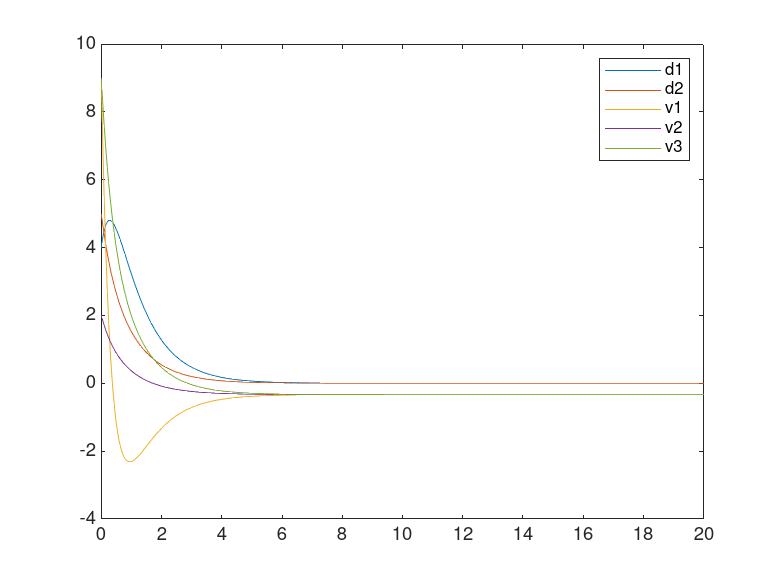

gr = [0;0;-1;-1;-1];
%gr = [0;0;0;0;0]; %si despreciamos completamente el efecto de la gravedad
sys = @(t,x)sistema_lineal(t,x,Ar,gr);
tf =20;
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],xini);%,opciones);
figure(1)
plot(t,x)
legend('d1','d2','v1','v2','v3')

Observamos que las distancias entre las naves se van a cero, luego convergen a un punto, sin embargo, es evidente que no se paran conservan una velocidad negativa que indica que en el fondo que están siendo atraídas por el planeta. Por supuesto, el análisis no es correcto ya que al desplazarse hacia el planeta la fuerza que las atrae es cada vez mayor y por tanto la velocidad cambiaría.

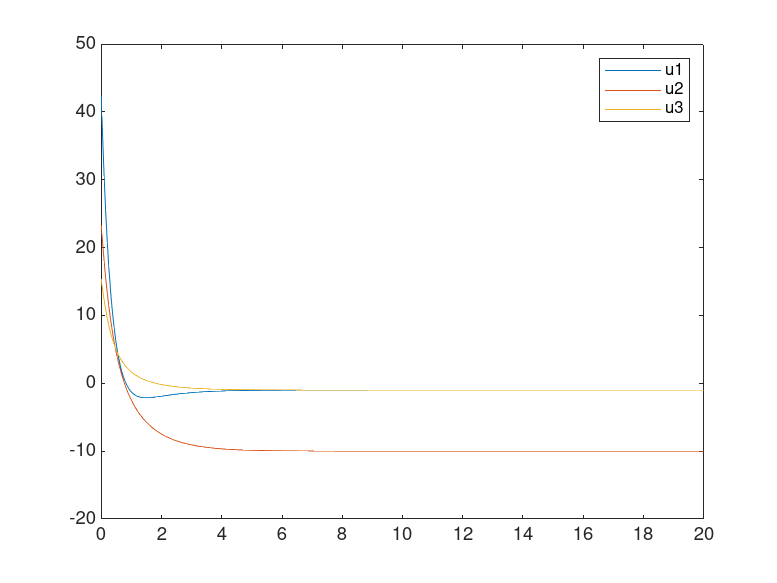

figure(2)
plot(t,K*x')
legend('u1','u2','u3')

## 3. Estudimamos la evolución de las variables de estado.

Calculamos la constante auxiliar de acoplo para ver qué pasa con el sistema

Kaux = [1 0 -1  0 0 0;0 0 1 0 -1 0;0 1 0 0 0 0; 0 0 0 1 0 0; 0 0 0 0 0 1]

Kaux =      1     0    -1     0     0     0
     0     0     1     0    -1     0
     0     1     0     0     0     0
     0     0     0     1     0     0
     0     0     0     0     0     1


Kf = K *Kaux

Kf =     2.0000    3.6667   -1.0000   -0.3333   -1.0000   -0.3333
  -10.0000   -3.3333   20.0000   36.6667  -10.0000   -3.3333
   -1.0000   -0.3333   -1.0000   -0.3333    2.0000    3.6667


Ac = A - B*Kf

Ac =          0    1.0000         0         0         0         0
   -1.9000   -3.6667    1.0000    0.3333    1.0000    0.3333
         0         0         0    1.0000         0         0
    1.0000    0.3333   -1.9000   -3.6667    1.0000    0.3333
         0         0         0         0         0    1.0000
    1.0000    0.3333    1.0000    0.3333   -1.9000   -3.6667


%la condicion inicial sigue siendo x0
%tomamos la g de partida, que es la del sistema
sys = @(t,x)sistema_lineal(t,x,Ac,g);
tf =20

tf = 20

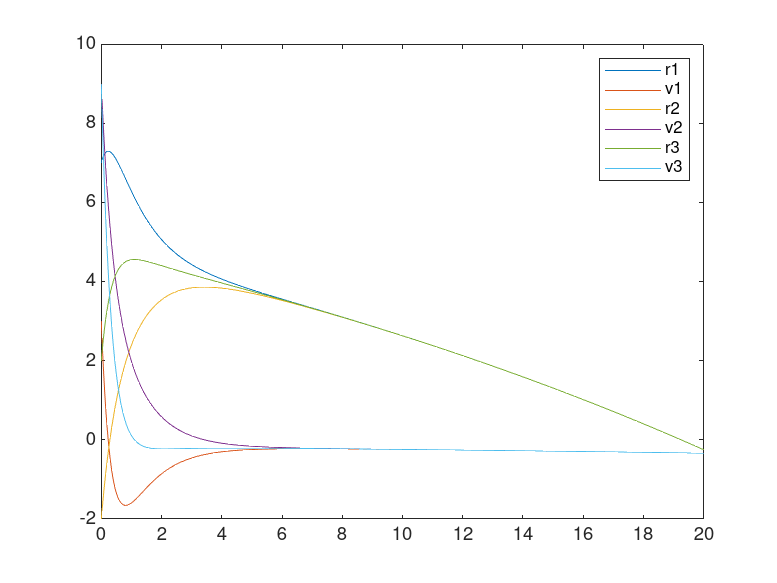

%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(2)
plot(t,x)
legend('r1','v1','r2','v2','r3','v3')

Se caen sobre el planeta y además el modelo linearizado nos muestra ya un aumento de la velocidad de caída sobre el planeta.

## 4. Control Integral para un comboy directo

Aplicamos control integral a las distancias y a la velocidad de la nave de transporte. Creamos una matriz $C_3$ adecuada, y analizamos la controlabilidad de la ampliada.

C3  = [1 0 0 0 0; 0 1 0 0 0; 0 0 0 1 0 ]

C3 =      1     0     0     0     0
     0     1     0     0     0
     0     0     0     1     0


Adamp = [Ad zeros(5,3);C3 zeros(3,3)]

Adamp =      0     0     1    -1     0     0     0     0
     0     0     0     1    -1     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0


Bdamp = [Bd;zeros(3)]

Bdamp =          0         0         0
         0         0         0
    1.0000         0         0
         0    0.1000         0
         0         0    1.0000
         0         0         0
         0         0         0
         0         0         0


rank(ctrb(Adamp,Bdamp))

ans = 8

Luego el sistema ampliado en controlable. También lo va a ser si cambiamos la velocidad a la que aplicamos control integral

## 5. Añadimos control integral y examinamos los resultados

lamdai2 = [-1,-1,-3,-3,-3,-4,-4,-4]

lamdai2 =     -1    -1    -3    -3    -3    -4    -4    -4


Ki2 = place(Adamp,Bdamp,lamdai2)

Ki2 =    17.2500    1.7500    7.7500   -0.5000   -0.2500    9.0000    3.0000   12.0000
  -17.5000   17.5000   -2.5000   75.0000   -2.5000  -30.0000   30.0000  120.0000
   -1.7500  -17.2500   -0.2500   -0.5000    7.7500   -3.0000   -9.0000   12.0000


Adcl = Adamp -Bdamp*Ki2

Adcl =          0         0    1.0000   -1.0000         0         0         0         0
         0         0         0    1.0000   -1.0000         0         0         0
  -17.2500   -1.7500   -7.7500    0.5000    0.2500   -9.0000   -3.0000  -12.0000
    1.7500   -1.7500    0.2500   -7.5000    0.2500    3.0000   -3.0000  -12.0000
    1.7500   17.2500    0.2500    0.5000   -7.7500    3.0000    9.0000  -12.0000
    1.0000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0


xinii = [xini;0;0;0]; %añadimos condiciones iniciales a las variables de error
yd = [3;3;4] %distancias de equilibrio y velocidad del comboy

yd =      3
     3
     4


Tenemos que modificar g para que solo afecte a la entrada al sistema pero no a los errores, Esto viene forzado por como hemos definido sistema_lineal_Io, que suma directamente la entrada g al sistema.

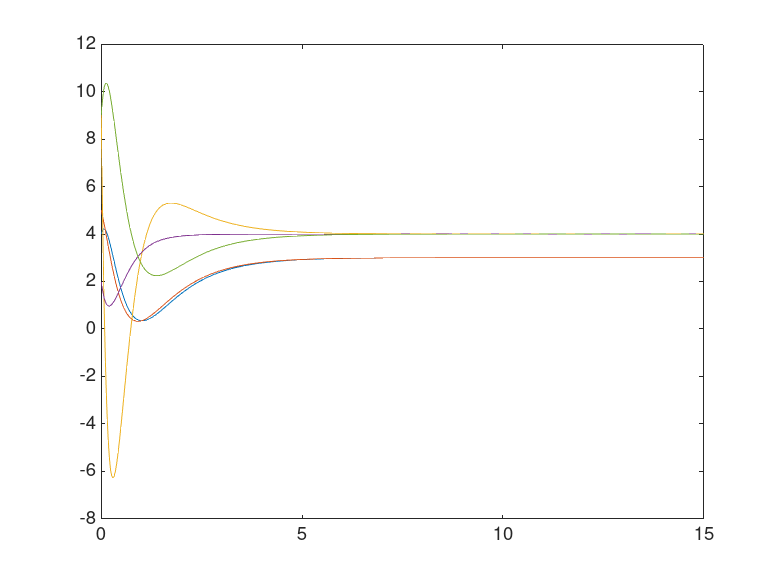

gi = [gr; zeros(length(yd),1)];
sys = @(t,x)sistema_lineal_IO(t,x,yd,Adcl,gi);
tf =15;
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],xinii);%,opciones);
figure(3)
plot(t,x(:,1:5))

%legend('r1','v1','r2','v2','r3','v3')

Efectivamente la distancia entre vehículos se va a cero, y además ahora tenemos la velocidad en el valor que queremos. Nos alejamos de Arakins a velocidad 4.

## 6. Para el sistema real basta con separar las ganacias del integrador.

Ki2p = Ki2(:,1:5)

Ki2p =    17.2500    1.7500    7.7500   -0.5000   -0.2500
  -17.5000   17.5000   -2.5000   75.0000   -2.5000
   -1.7500  -17.2500   -0.2500   -0.5000    7.7500


y crear una ganancia auxiliar para dar a cada nave su entrada (nos vale la de arriba)

Ki2i = Ki2(:,6:8)

Ki2i =     9.0000    3.0000   12.0000
  -30.0000   30.0000  120.0000
   -3.0000   -9.0000   12.0000


Kfp = [Ki2p*Kaux Ki2i]

Kfp =    17.2500    7.7500  -15.5000   -0.5000   -1.7500   -0.2500    9.0000    3.0000   12.0000
  -17.5000   -2.5000   35.0000   75.0000  -17.5000   -2.5000  -30.0000   30.0000  120.0000
   -1.7500   -0.2500  -15.5000   -0.5000   17.2500    7.7500   -3.0000   -9.0000   12.0000


Ahora creamos una ampliada con la planta real

C4 = [1 0 -1 0 0 0; 0 0 1 0 -1 0; 0 0 0 1 0 0]

C4 =      1     0    -1     0     0     0
     0     0     1     0    -1     0
     0     0     0     1     0     0


Aramp = [A zeros(6,3); C4 zeros(3)]

Aramp =          0    1.0000         0         0         0         0         0         0         0
    0.1000         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0
         0         0    0.1000         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0    0.1000         0         0         0         0
    1.0000         0   -1.0000         0         0         0         0         0         0
         0         0    1.0000         0   -1.0000         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0


Bramp = [B;zeros(3)]

Bramp =          0         0         0
    1.0000         0         0
         0         0         0
         0    0.1000         0
         0         0         0
         0         0    1.0000
         0         0         0
         0         0         0
         0         0         0


Acl = Aramp -Bramp*Kfp

Acl =          0    1.0000         0         0         0         0         0         0         0
  -17.1500   -7.7500   15.5000    0.5000    1.7500    0.2500   -9.0000   -3.0000  -12.0000
         0         0         0    1.0000         0         0         0         0         0
    1.7500    0.2500   -3.4000   -7.5000    1.7500    0.2500    3.0000   -3.0000  -12.0000
         0         0         0         0         0    1.0000         0         0         0
    1.7500    0.2500   15.5000    0.5000  -17.1500   -7.7500    3.0000    9.0000  -12.0000
    1.0000         0   -1.0000         0         0         0         0         0         0
         0         0    1.0000         0   -1.0000         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0


x0i = [x0;0;0;0]; %añadimos condiciones iniciales a las variables de error
yd = [3;3;4] %distancia para el comboy

yd =      3
     3
     4


gint = [g;zeros(length(yd),1)] %de nuevo modificamos la entrada de la gravedad para añadir zeros en las entradas de los errores 

gint =      0
    -1
     0
    -1
     0
    -1
     0
     0
     0


sys = @(t,x)sistema_lineal_IO(t,x,yd,Acl,gint);
tf =15

tf = 15

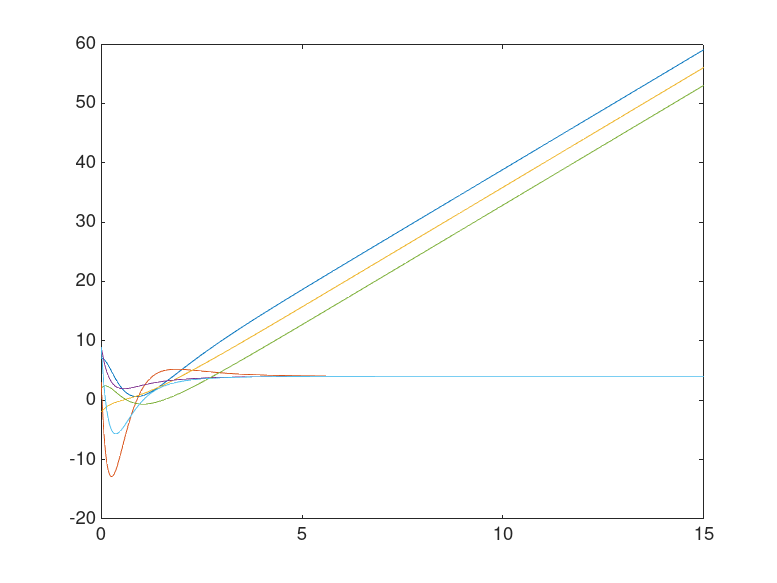

%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0i);%,opciones);
figure(4)
plot(t,x(:,1:6))

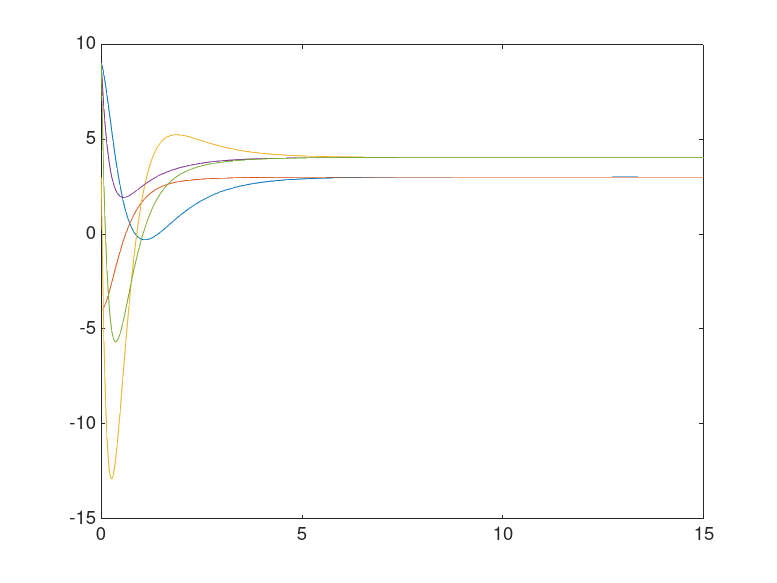

figure(5)

dvs = [x(:,1)-x(:,3) x(:,3)-x(:,5) x(:,2) x(:,4) x(:,6)];
plot(t,dvs)

Se alejan efectivamente y mantienen entre ellos la distancia.

## 7. Estimador.

Vamos a diseñar ahora un estimador. Empezamos por definir una matriz C que solo obtenga las posiciones.

Y comprobar que el sistema es observable

C = [Ci padc padc;padc Ci padc; padc padc Ci]

C =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0


obcs1 = rank(obsv(A,C))

obcs1 = 6

## 8. Calculamos las ganancias del observador y diseñamos el sistema ampliado

Ahora obtenemos la ganancia del observador

lamdao = [-5, -5, -5, -2, -2, -2]

lamdao =     -5    -5    -5    -2    -2    -2


L = place(A',C',lamdao)'

L =     7.0000   -0.0000   -0.0000
   10.1000   -0.0000    0.0000
   -0.0000    7.0000   -0.0000
   -0.0000   10.1000   -0.0000
   -0.0000    0.0000    7.0000
   -0.0000    0.0000   10.1000


Atot = [A -B*Ki2p*Kaux -B*Ki2i;
    L*C A-B*Ki2p*Kaux-L*C -B*Ki2i;
    C4 zeros(3,9)]

Atot =          0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1000         0         0         0         0         0  -17.2500   -7.7500   15.5000    0.5000    1.7500    0.2500   -9.0000   -3.0000  -12.0000
         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.1000         0         0         0    1.7500    0.2500   -3.5000   -7.5000    1.7500    0.2500    3.0000   -3.0000  -12.0000
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1000         0    1.7500    0.2500   15.5000    0.5000  -17.2500   -7.7500    3.0000    9.0000  -12.0000
    7.0000         0   -0.0000         0   -0.0000         0   -7.0000    1.0000    0.0

## 9. Obtenemos el último dibujillo

x0C = [x0;0;0;0;0;0;0;0;0;0]; %añadimos condiciones iniciales (zeros) a los estados etimados
yd = [3;3;4] %distancia para el rendevu

yd =      3
     3
     4


goi = [g;g;zeros(length(yd),1)]

goi =      0
    -1
     0
    -1
     0
    -1
     0
    -1
     0
    -1


sys = @(t,x)sistema_lineal_IO(t,x,yd,Atot,goi);
tf =15

tf = 15

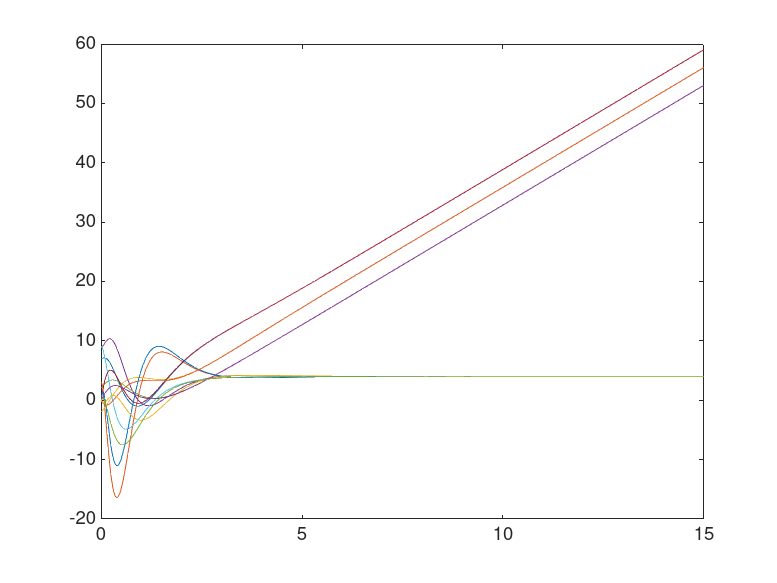

%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0C);%,opciones);
figure(6)
plot(t,x(:,1:12))

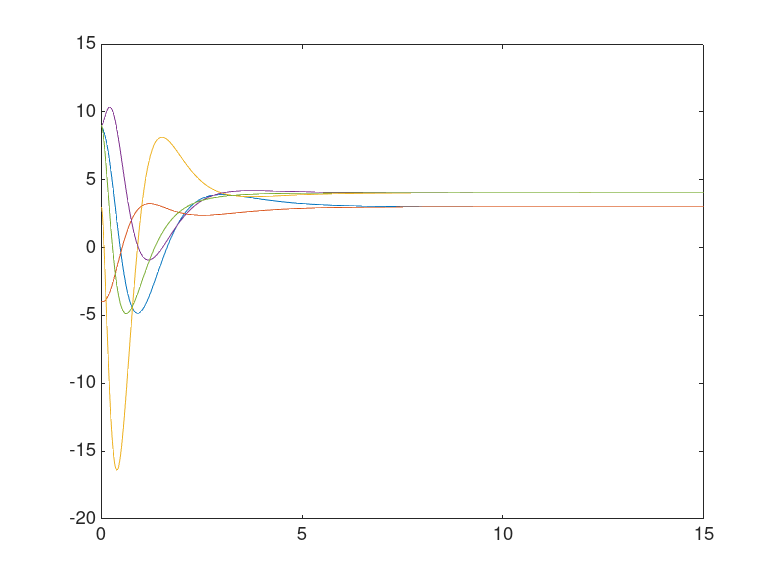

figure(7)

dvs = [x(:,1)-x(:,3) x(:,3)-x(:,5) x(:,2) x(:,4) x(:,6)];
plot(t,dvs)

function xdot = sistema_lineal(t,x,A,g)
%simple y llano
xdot = A*x + g;
end
function xdot = sistema_lineal_IO(t,x,yd,A,g)
%modificamos el sistema lineal para ponerlo en modo realimentación
%Debemos añadir la entrada al error, que corresponde a yd
xdot = A*x+[zeros(size(x,1)-length(yd),1);-yd]+g;
end
